# COVID-19 spread

latex2markdown('covid19_live_script')

Unrecognized function or variable 'mergeSameEnvironments'.

Error in latex2markdown (line 79)
str = mergeSameEnvironments(str,"lstlisting");

## Data

 
breakdown = false;     regione="Abruzzo";

if breakdown
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-regioni/dpc-covid19-ita-regioni.csv","dati.csv") ;
else
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv","dati.csv") ;
end



dati=readtable(data_location);
delete dati.csv

if breakdown
    dati = dati(dati.denominazione_regione==regione, :);
end
dati = dati(:,{'data','totale_casi'});
dati.data = datetime(dati.data,"Format","uuuu-MM-dd ");
dati.data = dateshift(dati.data, 'start', 'day');

disp(dati)

       data        totale_casi
    ___________    ___________

    2020-02-24          229   
    2020-02-25          322   
    2020-02-26          400   
    2020-02-27          650   
    2020-02-28          888   
    2020-02-29         1128   
    2020-03-01         1694   
    2020-03-02         2036   
    2020-03-03         2502   
    2020-03-04         3089   
    2020-03-05         3858   
    2020-03-06         4636   
    2020-03-07         5883   
    2020-03-08         7375   
    2020-03-09         9172   
    2020-03-10        10149   
    2020-03-11        12462   
    2020-03-12        15113   
    2020-03-13        17660   
    2020-03-14        21157   
    2020-03-15        24747   
    2020-03-16        27980   
    2020-03-17        31506   
    2020-03-18        35713   
    2020-03-19        41035   
    2020-03-20        47021   
    2020-03-21        53578   
    2020-03-22        59138   



confirmed_cases = dati.totale_casi;
day_num = datenum(dati.data - dati.data(1));
day_date = dati.data;
delta = finite_difference(confirmed_cases);
CURRENT = day_num(end);

## Data fitting

[linfit, lin_r] = fit(day_num, confirmed_cases, 'poly1');
[expfit, exp_r] = fit(day_num, confirmed_cases, 'exp1');
[logfit, log_r] = logisticFit(day_num, confirmed_cases);

## Plotting

fig_width=1500;
fig_height= 900;

### Linear fitting

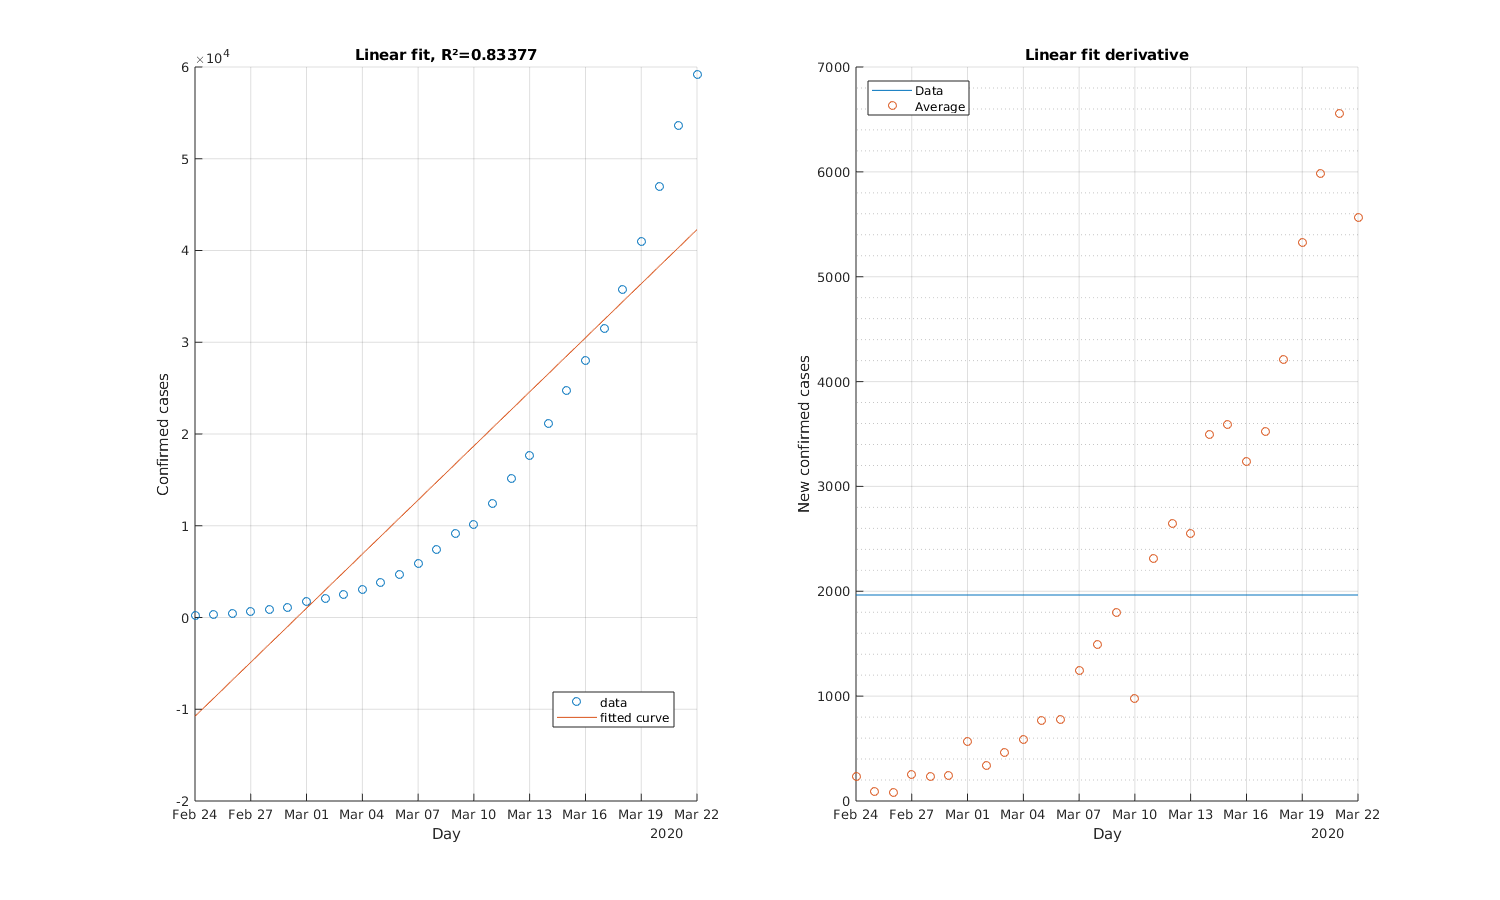

figure("Name",'Linear interpolation', 'Position', [10 10 fig_width fig_height]);
subplot(1,2,1)

hold on
scatter(day_date, confirmed_cases);
plot(day_date, linfit(day_num), "-");
grid on

title("Linear fit, R²="+lin_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
legend({'data','fitted curve'},"Location","best")
hold off

% increase
subplot(1,2,2)
hold on


derivative_lin = differentiate(linfit, day_num);
plot(day_date,derivative_lin);

scatter(day_date, delta);
legend({'Data','Average'},"Location","best")

hold off
grid on
grid minor

title("Linear fit derivative")
ylabel("New confirmed cases")
xlabel("Day")



[rho, pval] = corr(delta,derivative_lin);
disp("Correlation of the derivative with actual icreases: "+rho);

Correlation of the derivative with actual icreases: 5.2893e-17


disp("P-value: "+pval);

P-value: 1


disp("");
disp("Predicted total confirmed cases tomorrow: "+round(linfit(CURRENT+1)));

Predicted total confirmed cases tomorrow: 44242


disp("There are, on average, "+linfit.p1+" new cases each day.")

There are, on average, 1964.6412 new cases each day.


### Exponential fitting

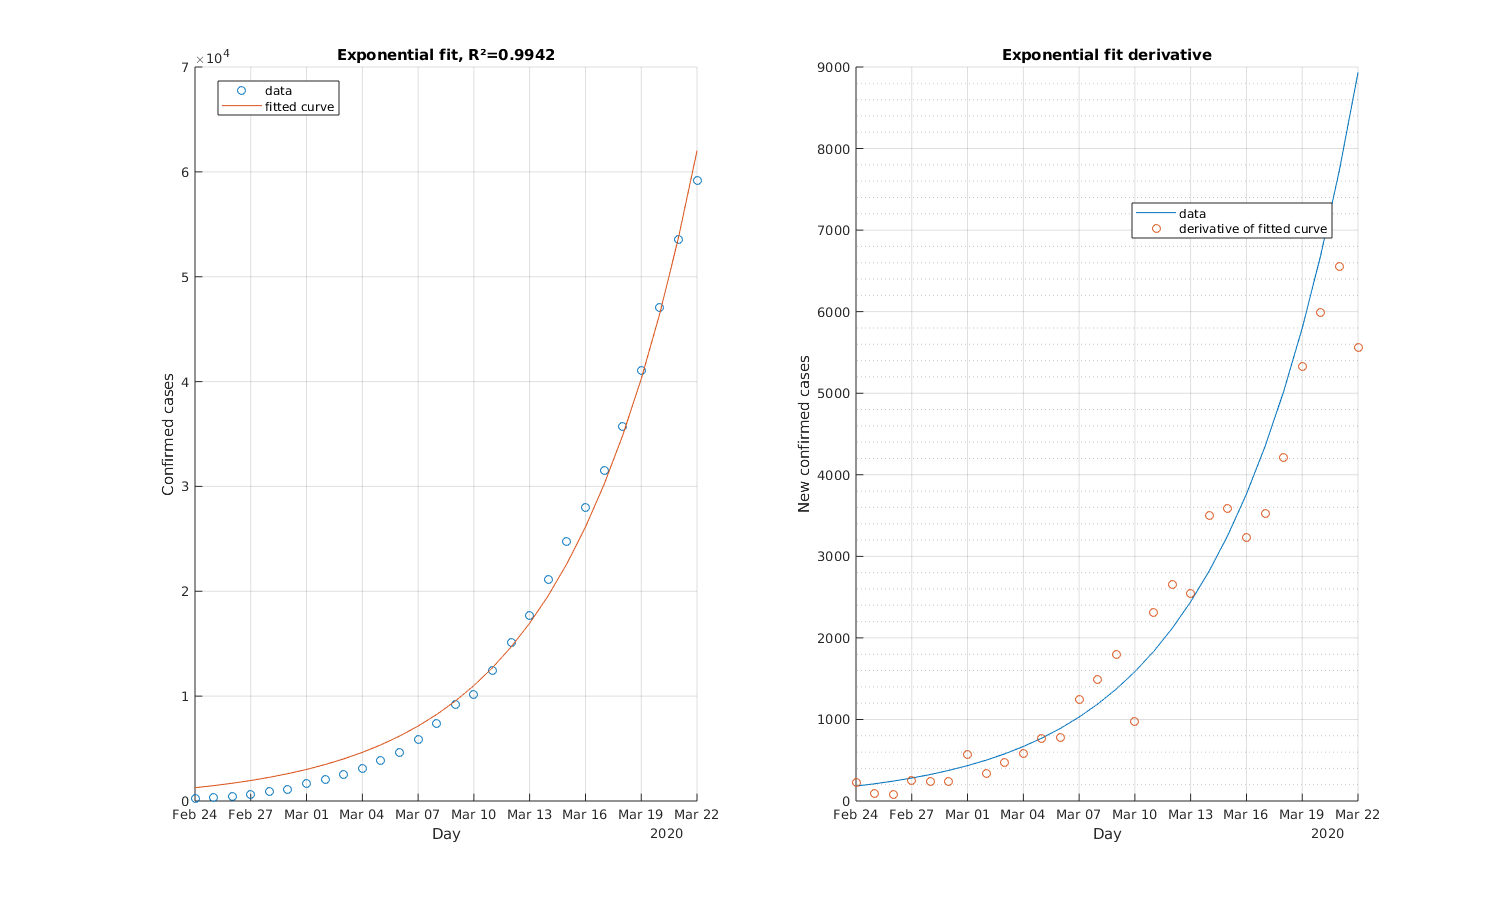

figure("Name",'Exponential interpolation', 'Position', [10 10 fig_width fig_height]);
%total number
subplot(1,2,1)
hold on
scatter(day_date,confirmed_cases);
plot(day_date, expfit(day_num), "-");
grid on

title("Exponential fit, R²="+exp_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
legend({'data','fitted curve'},"Location","best")
hold off

%increase

subplot(1,2,2)
hold on


derivative_exp = differentiate(expfit, day_num);
plot(day_date,derivative_exp);

scatter(day_date, delta);
legend({'data','derivative of fitted curve'},"Location","best")

hold off
grid on
grid minor

title("Exponential fit derivative")
ylabel("New confirmed cases")
xlabel("Day")


[rho, pval] = corr(delta,derivative_exp);
disp("Correlation of the derivative with actual icreases: "+rho);

Correlation of the derivative with actual icreases: 0.9646


disp("P-value: "+pval);

P-value: 1.4245e-16


disp("");
disp("+"+expfit.b*100+"% new confirmed cases each day")

+14.4053% new confirmed cases each day


disp("Predicted total confirmed cases tomorrow: "+round(expfit(CURRENT+1)));

Predicted total confirmed cases tomorrow: 71622


disp("Predicted new cases for tomorrow: "+round(differentiate(expfit,CURRENT+1)))

Predicted new cases for tomorrow: 10317


## Three parameters logistic fitting

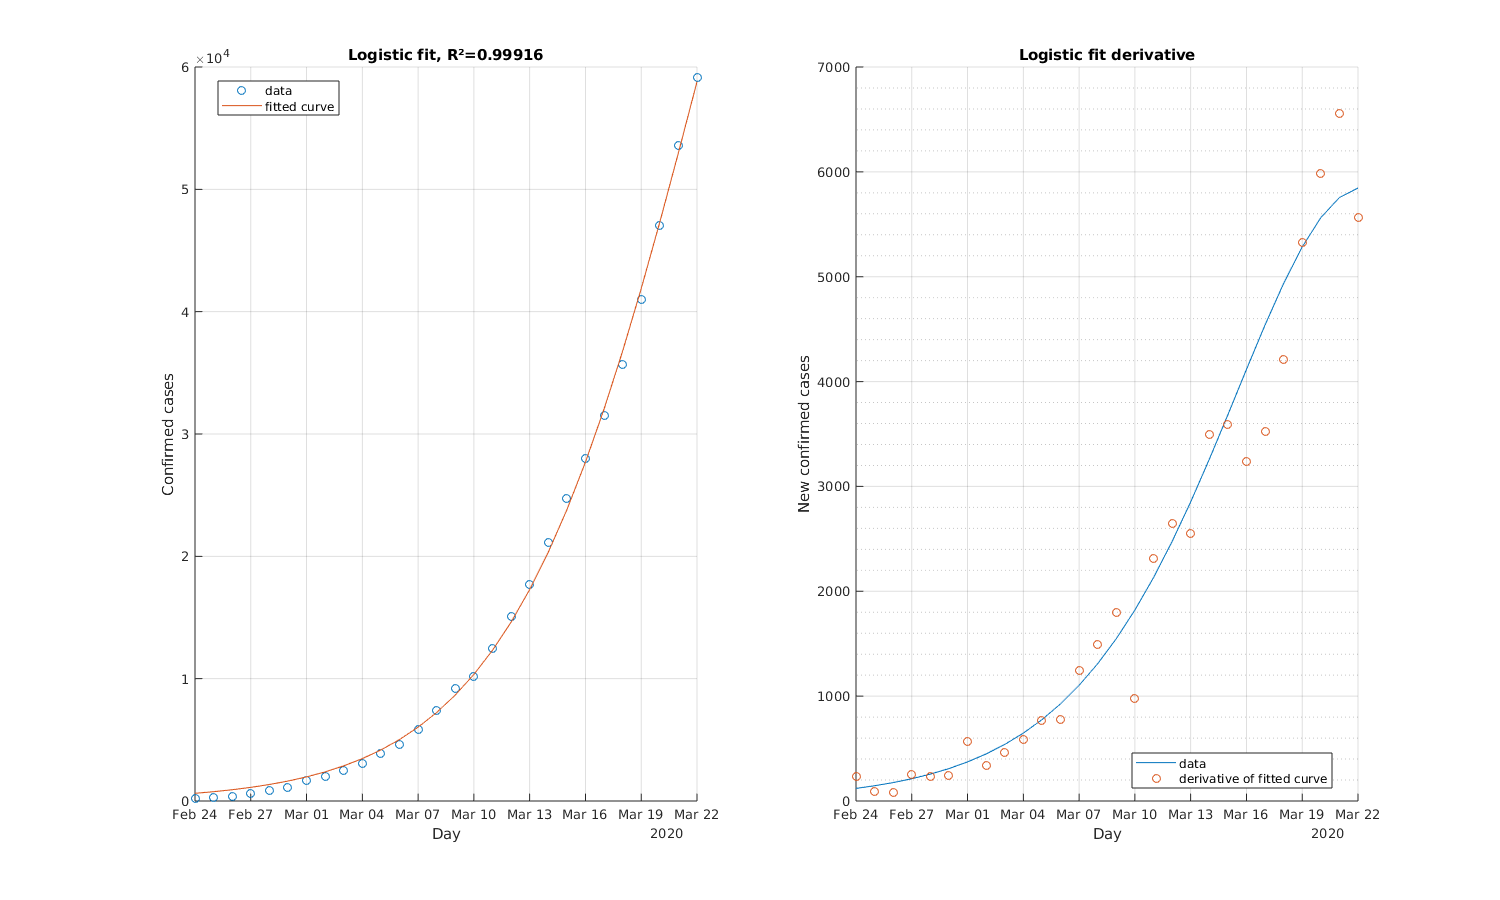

figure("Name",'log1', 'Position', [10 10 fig_width fig_height]);

% total number
subplot(1,2,1);
hold on

scatter(day_date,confirmed_cases);
plot(day_date, logfit(day_num), "-");
grid on

title("Logistic fit, R²="+log_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
legend({'data','fitted curve'},"Location","best")
hold off

%increase
subplot(1,2,2);
hold on


derivative = differentiate(logfit, day_num);
plot(day_date,derivative);

scatter(day_date, delta);
legend({'data','derivative of fitted curve'},"Location","best")

hold off
grid on
grid minor

title("Logistic fit derivative")
ylabel("New confirmed cases")
xlabel("Day")


[rho, pval] = corr(delta,derivative);
disp("Correlation of the derivative with actual icreases: "+rho);

Correlation of the derivative with actual icreases: 0.98037


disp("P-value: "+pval);

P-value: 7.3014e-20


disp("");
disp("Predicted total confirmed cases tomorrow: "+round(logfit(CURRENT+1)));

Predicted total confirmed cases tomorrow: 64645


disp("Predicted increase in cases tomorrow:     "+round(differentiate(logfit,CURRENT+1)));

Predicted increase in cases tomorrow:     5831


## Future projections

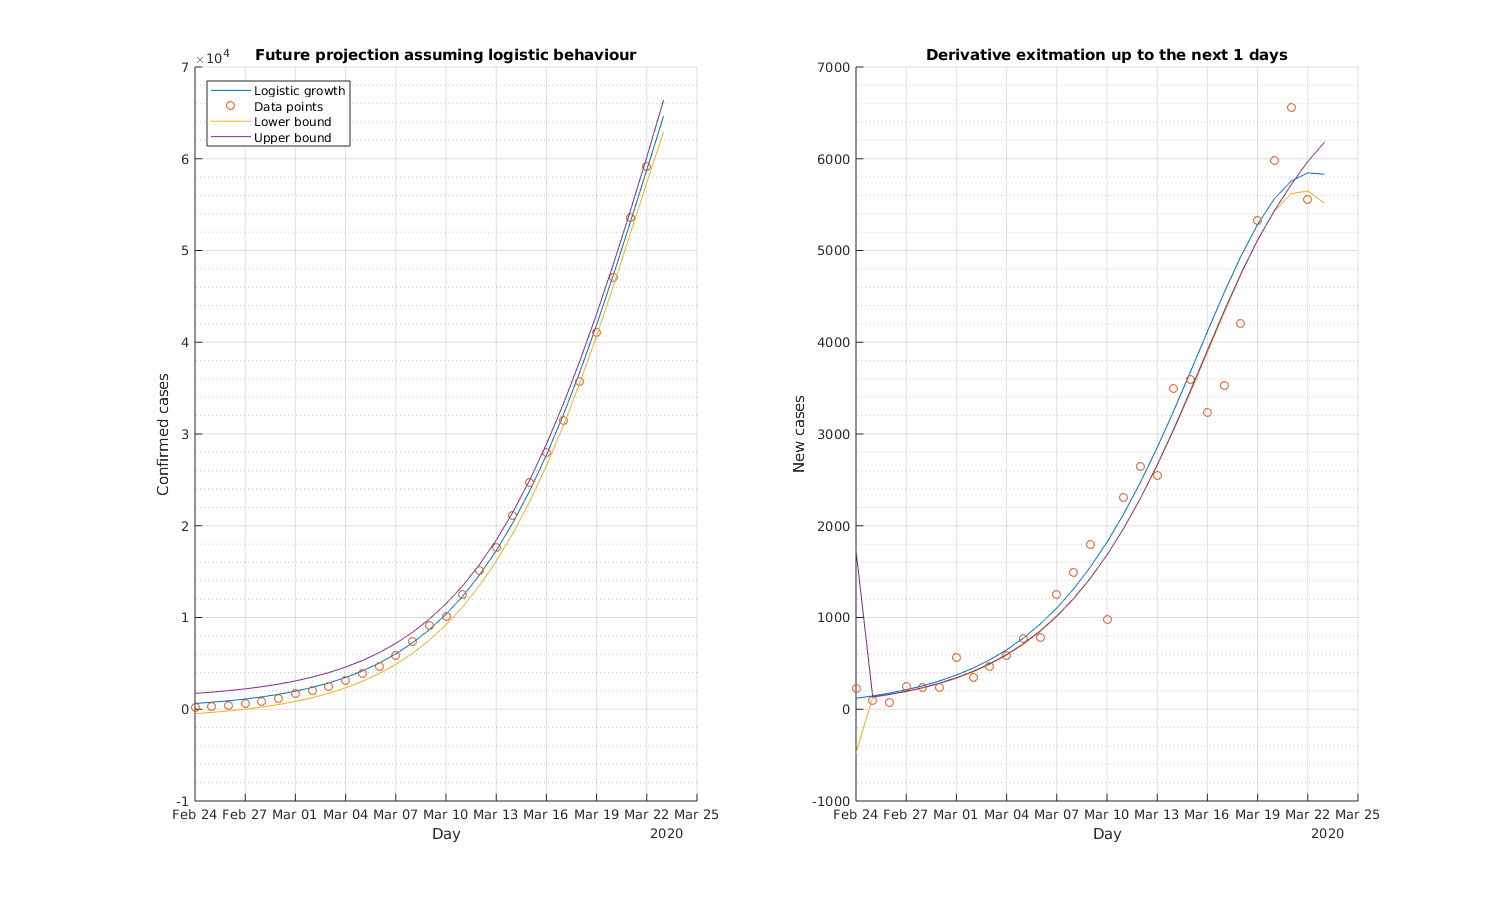

look_ahead_days = 1;
extended_date_set=extend_date_array(day_date,look_ahead_days);
compare=false;
error_bars=true;    confidence = 0.95;


if confidence >= 1
    confidence=1;
    disp("Confidence interval must be between 0 and 1, clipped to "+confidence)
elseif confidence <= 0
    confidence=0.001;
    disp("Confidence interval must be between 0 and 1, clipped to "+confidence)
end

figure("Name","Future projections assuming a logistic model", 'Position', [10 10 fig_width fig_height]);

%total number
subplot(1,2,1);
hold on

plot(extended_date_set,logfit(0:(CURRENT+look_ahead_days)))


grid on
grid minor
title("Future projection assuming logistic behaviour")
ylabel("Confirmed cases")
xlabel("Day")
scatter(day_date,confirmed_cases)

legend({'Logistic growth','Data points'}, "Location","best");

if compare
    plot(extended_date_set,expfit(0:(CURRENT+look_ahead_days)))
    title("Future projection logistic vs exponential")
    legend({'Logistic growth','Data points', 'Exponential growth'}, "Location","best");
end
if error_bars
    log_ci = predint(logfit,0:(CURRENT+look_ahead_days),confidence);
    plot(extended_date_set,log_ci,'LineWidth',0.001);
    legend({'Logistic growth','Data points','Lower bound','Upper bound'}, "Location","best");

end
hold off

% Derivative
subplot(1,2,2)
hold on

plot(extended_date_set,differentiate(logfit, 0:(CURRENT+look_ahead_days)));
scatter(day_date,delta);
grid on
grid minor

title("Derivative exitmation up to the next " + look_ahead_days+" days");
ylabel("New cases")
xlabel("Day")
if compare
    plot(extended_date_set,differentiate(expfit, 0:(CURRENT+look_ahead_days)));
end
if error_bars
    plot(extended_date_set, finite_difference(log_ci(:,1)));
    plot(extended_date_set, finite_difference(log_ci(:,2)));
end

hold off

## Comparison with past projections:

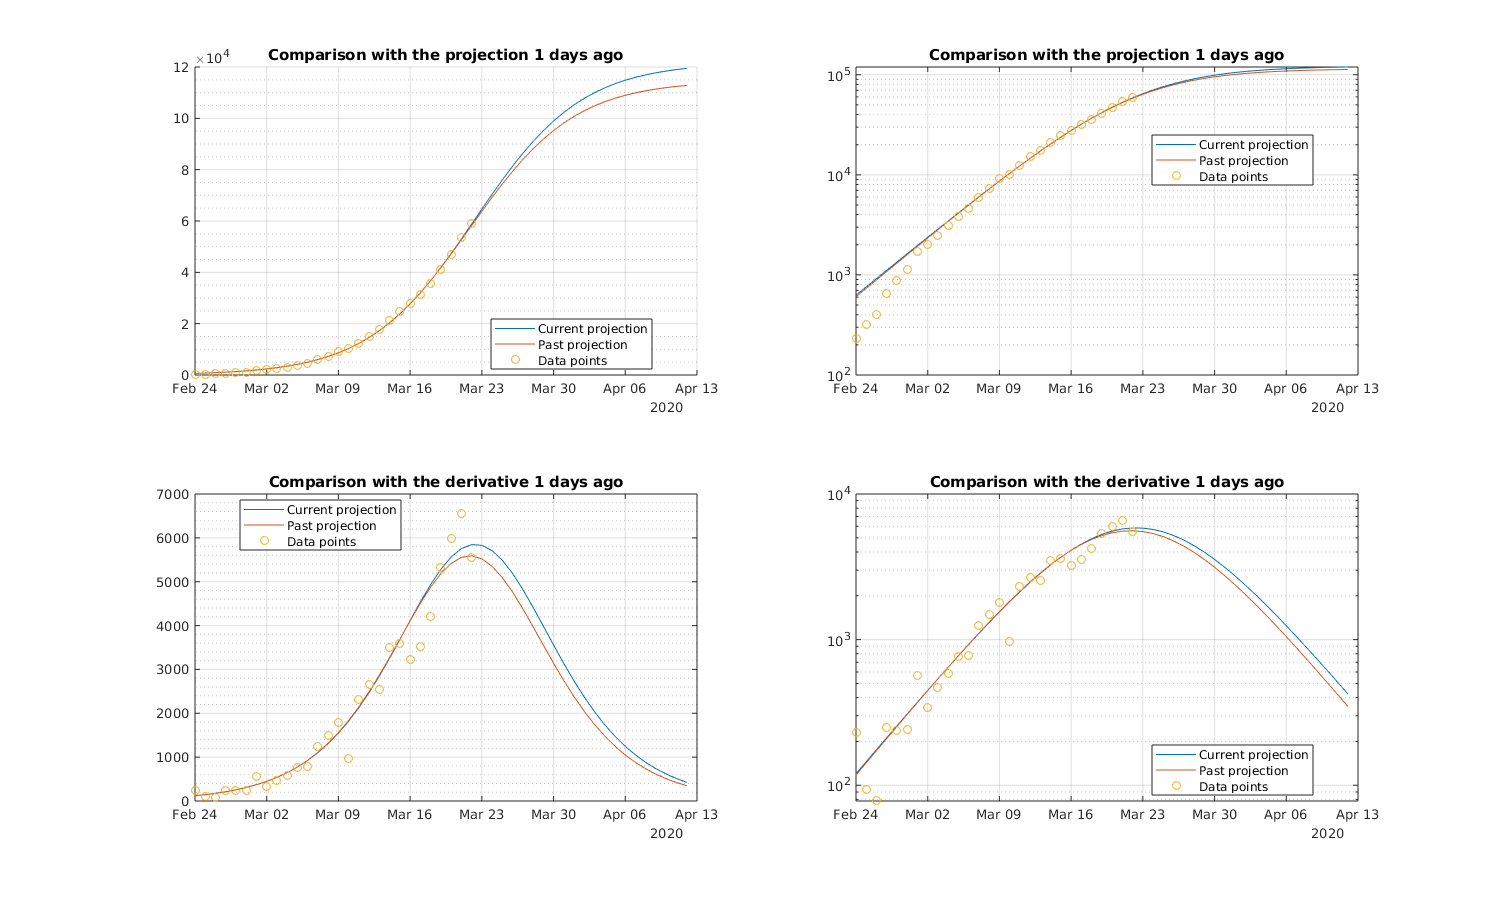

look_ahead_days = 21;
look_behind_days = 1;

model="Logistic";

reduced_day=day_num(1:(end-look_behind_days));
reduced_cases=confirmed_cases(1:(end-look_behind_days));
extended_date_set=extend_date_array(day_date,look_ahead_days);


if model == "Logistic"
    model_current = logfit;
    model_past = logisticFit(reduced_day, reduced_cases );
else
    model_current = expfit;
    model_past = fit(reduced_day, reduced_cases, 'exp1');
end

figure("Name","Comparison of the future projections "+look_behind_days+" days ago with the projection today", 'Position', [10 10 fig_width fig_height]);

subplot(2,2,1);
hold on
plot(extended_date_set,model_current(0:(CURRENT+look_ahead_days)))
grid minor
grid on
plot(extended_date_set,model_past(0:(CURRENT+look_ahead_days)))
scatter(day_date, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off


subplot(2,2,2);
semilogy(extended_date_set,model_current(0:(CURRENT+look_ahead_days)))
grid minor
grid on
hold on
semilogy(extended_date_set,model_past(0:(CURRENT+look_ahead_days)))
scatter(day_date, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off


subplot(2,2,3);
plot(extended_date_set,differentiate(model_current, 0:(CURRENT+look_ahead_days)));
hold on
plot(extended_date_set,differentiate(model_past, 0:(CURRENT+look_ahead_days)));
hold on
scatter(day_date,delta);
title("Comparison with the derivative "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
grid minor
grid on
hold off


subplot(2,2,4);
semilogy(extended_date_set,differentiate(model_current, 0:(CURRENT+look_ahead_days)));
hold on
semilogy(extended_date_set,differentiate(model_past, 0:(CURRENT+look_ahead_days)));
hold on
scatter(day_date,delta);
title("Comparison with the derivative "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
grid minor
grid on
hold off

function [difference] = finite_difference(x)
    subtract = zeros(length(x));
    subtract = subtract(:,1);
    subtract(2:end)=x(1:(end-1));
    difference = x-subtract;
end

function [date_array2] = extend_date_array(date_array, extention)
    date_array2=date_array(1):(date_array(end)+extention);
end